clear all
clear

Загрузка параметров

load curvefitting.mat

Описание данных с помощью функций (пытаемся использовать полиномы n-ой степени)

%   Строим модель, пытаемся описать все данные полиномом 5 степени poly5 
%   Все значения normalized by mean 1.061e+04 and std 2989


%   Разделить значения по расходам
%   значения начиная с 7500 (6 ая строка)

for i = 6:1:11

%   получение сил/моментов, соответствующих расходам
%   для каждой из сил строим и интерполируем(аппроксимируем) зависимость от частоты

%   Сохранение соответств. сил/моментов в 

Fr_cell{i-5}=Fr_comb{1,i};
Fx_cell{i-5}=Fx_comb{1,i};
Fy_cell{i-5}=Fy_comb{1,i};
Fz_cell{i-5}=Fz_comb{1,i};

Mr_cell{i-5}=Mr_comb{1,i};
Mx_cell{i-5}=Mx_comb{1,i};
My_cell{i-5}=My_comb{1,i};
Mz_cell{i-5}=Mz_comb{1,i};


end
%   объединяем, получаем ячейки, 
%   где строки - значения по x,y,z,r а столбцы - расходы
%   в самих ячейках вектор из 6 значений (точек) силы/момента для данного
%   расхода по возрастанию идут значения сил от скорости вращения от 7500 до 15000 

F_all=[Fx_cell; Fy_cell; Fz_cell; Fr_cell];
M_all = [Mx_cell; My_cell; Mz_cell; Mr_cell];

FplusM = [F_all; M_all];

save("FplusM.mat","FplusM", "F_all","F_all","RPM_comb");
% FM_all = {F_all; M_all}
% Fr_cell(1,i) - получение силы, соответствующей расходу

Интерполяция визуально для каждого значения силы или момента

k = 1

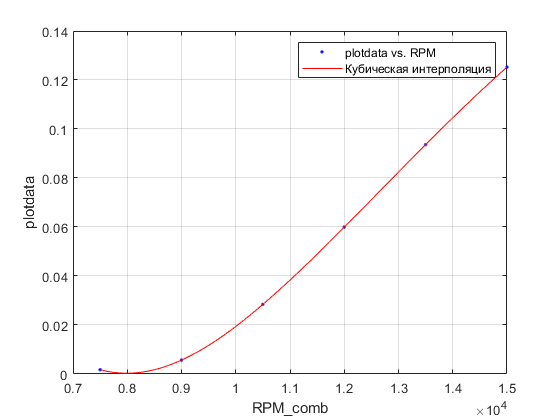

k = 2

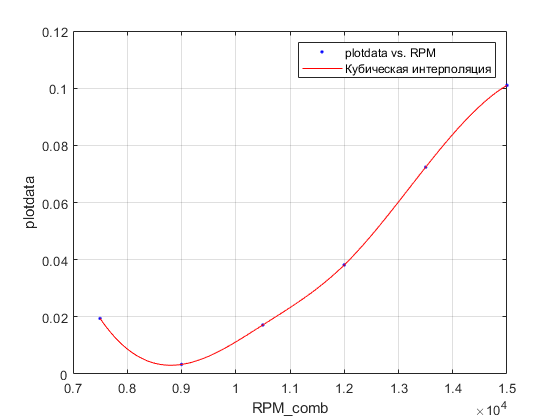

k = 3

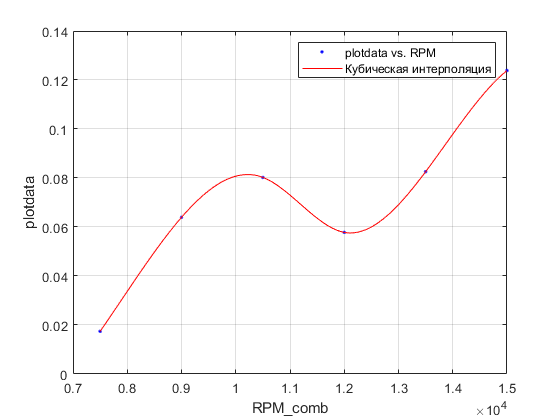

k = 4

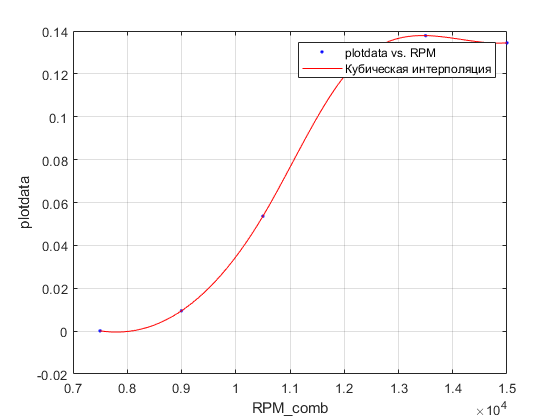

k = 5

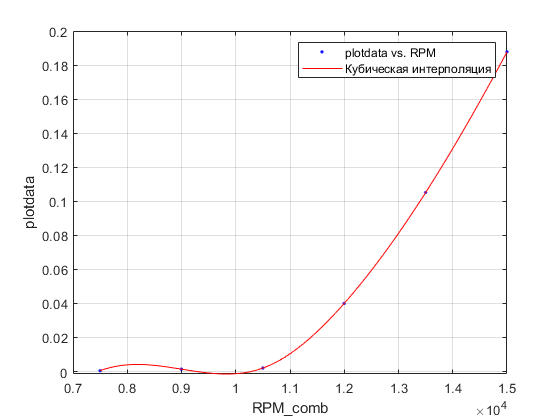

k = 6

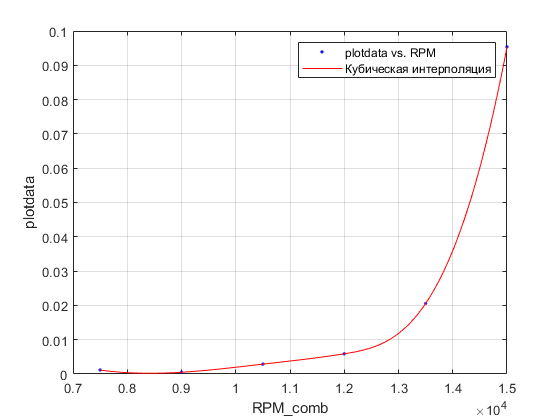

k = 7

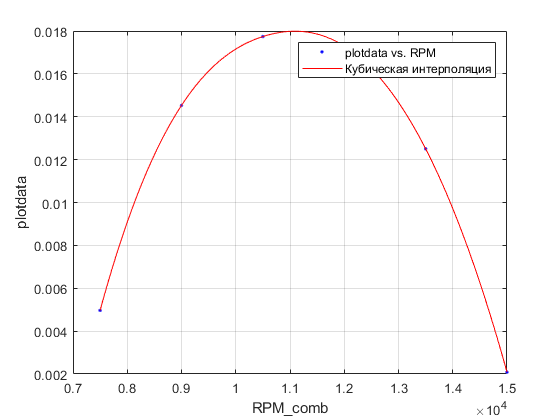

k = 8

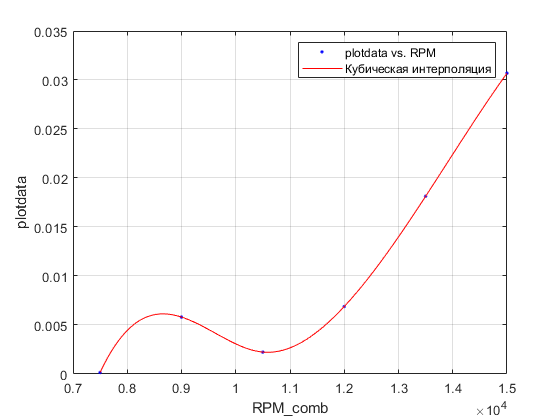

k = 9

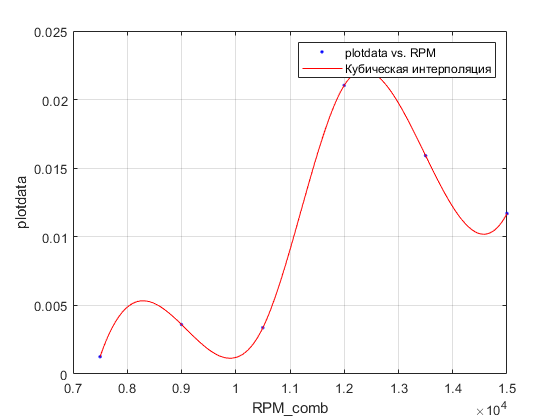

k = 10

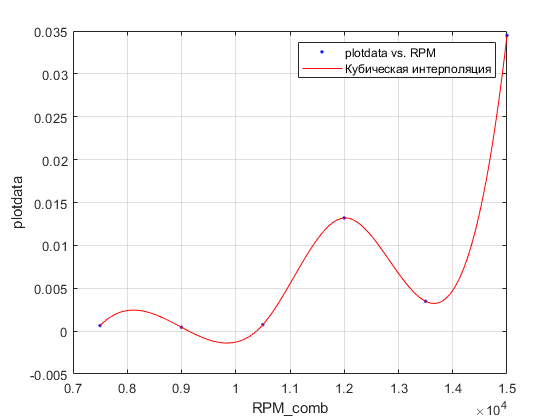

k = 11

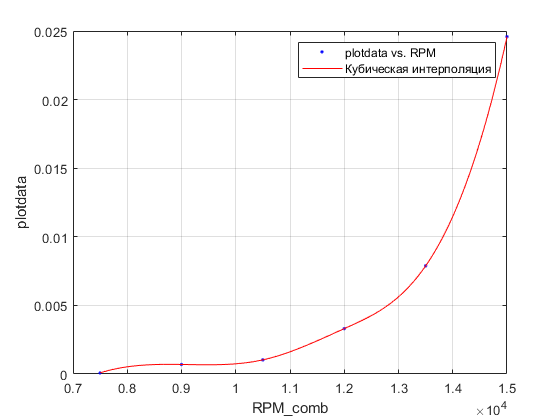

k = 12

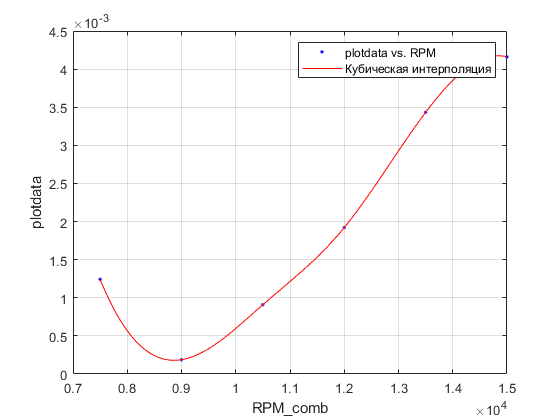

k = 13

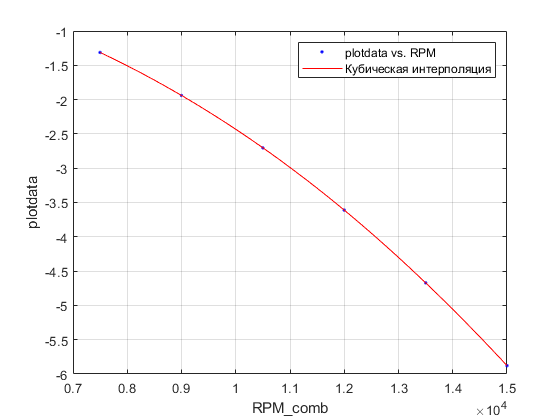

k = 14

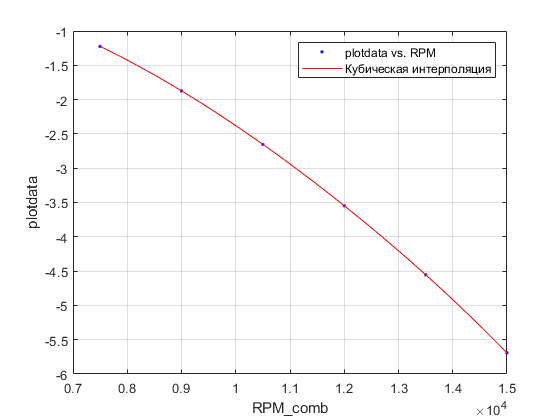

k = 15

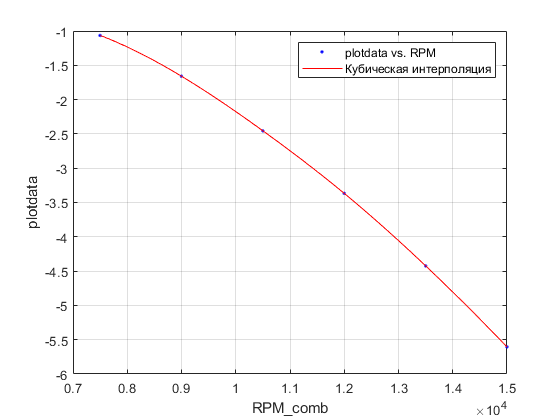

k = 16

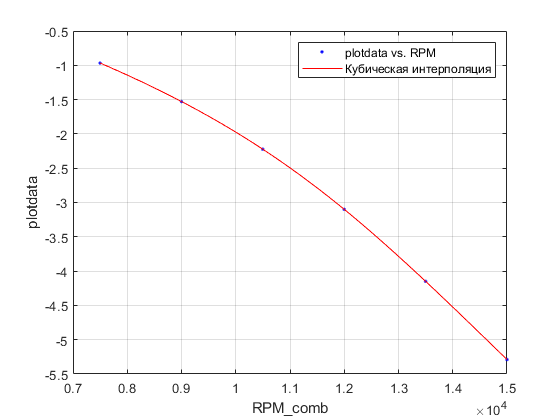

k = 17

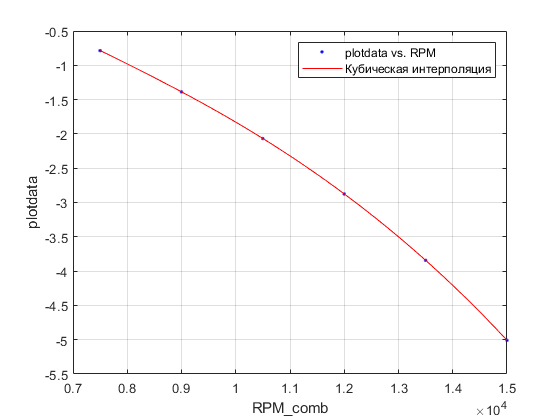

k = 18

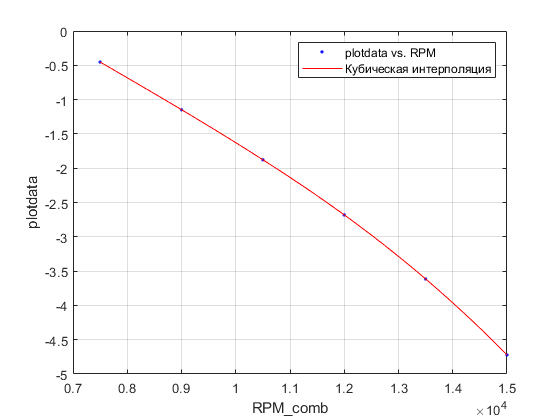

k = 19

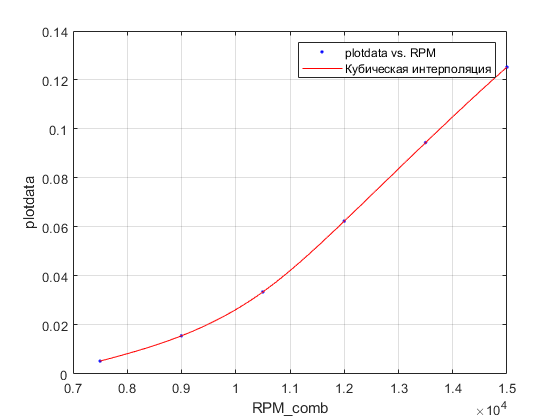

k = 20

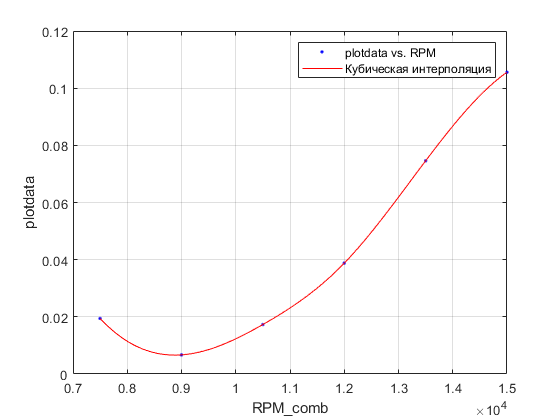

k = 21

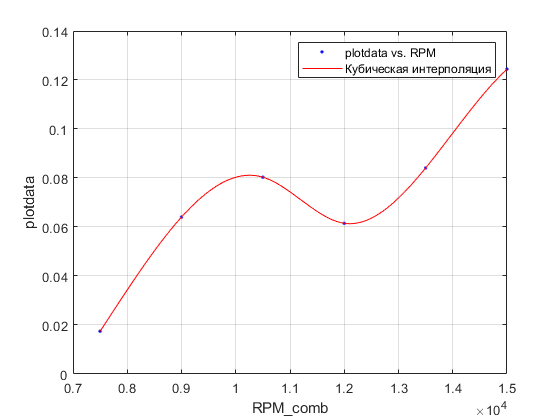

k = 22

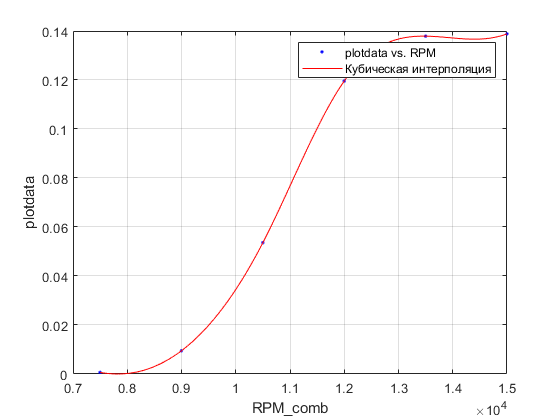

k = 23

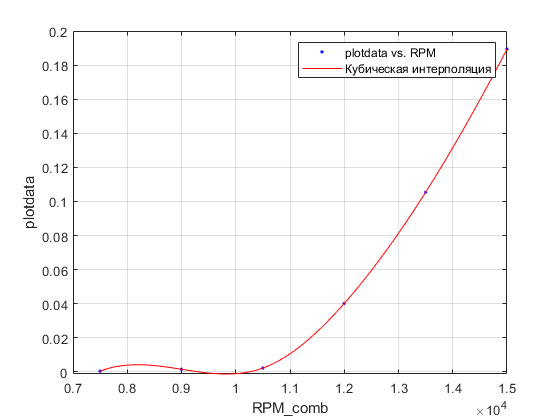

k = 24

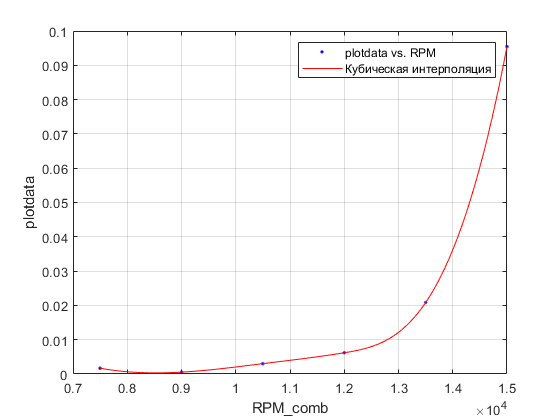

k = 25

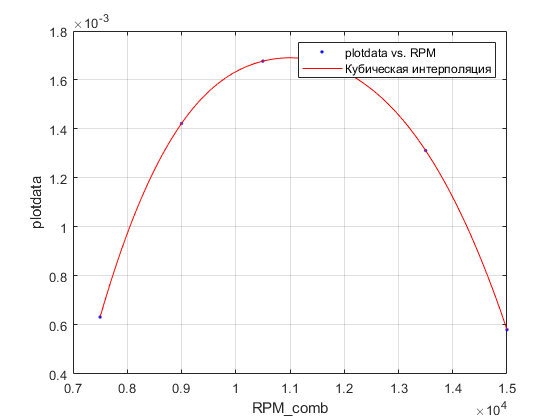

k = 26

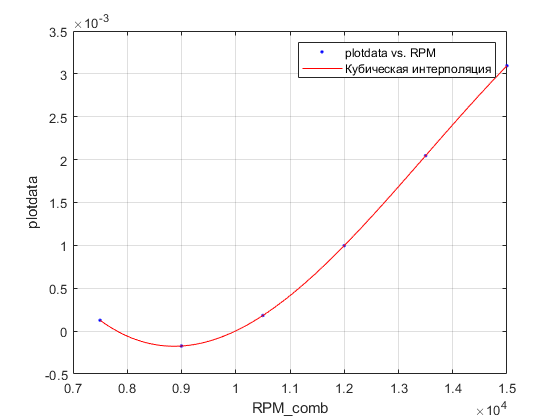

k = 27

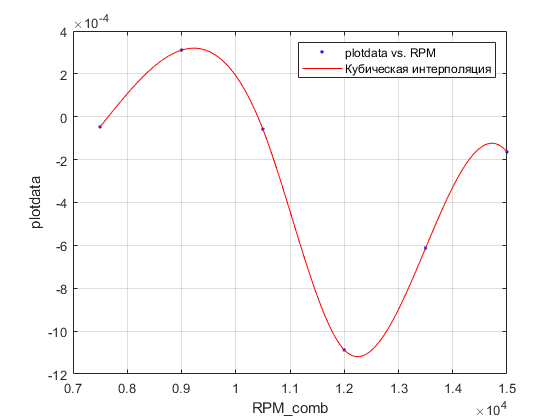

k = 28

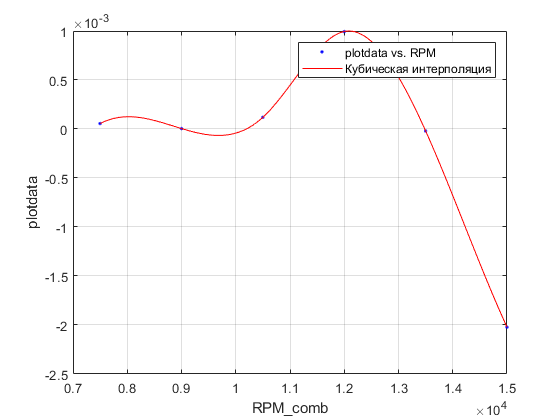

k = 29

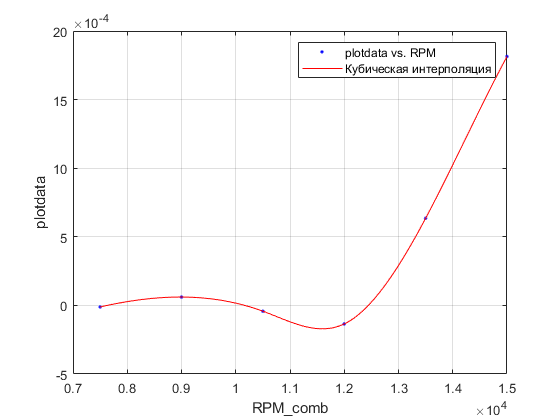

k = 30

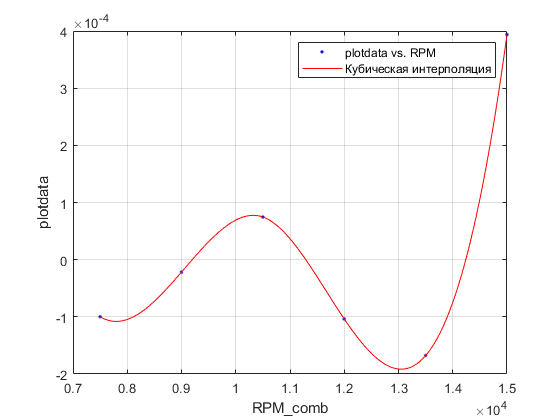

k = 31

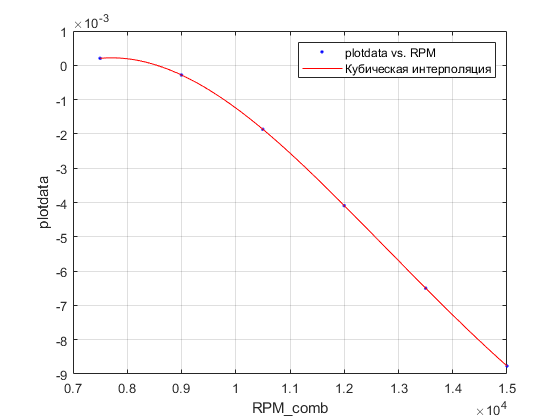

k = 32

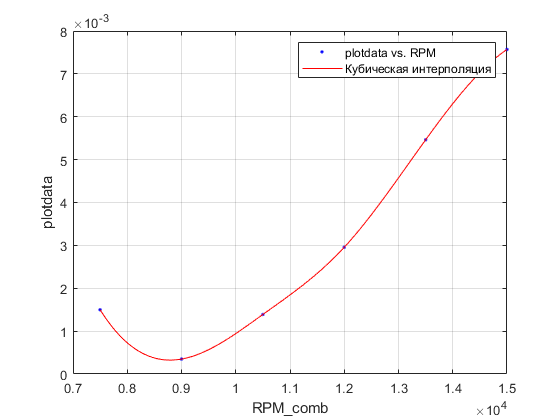

k = 33

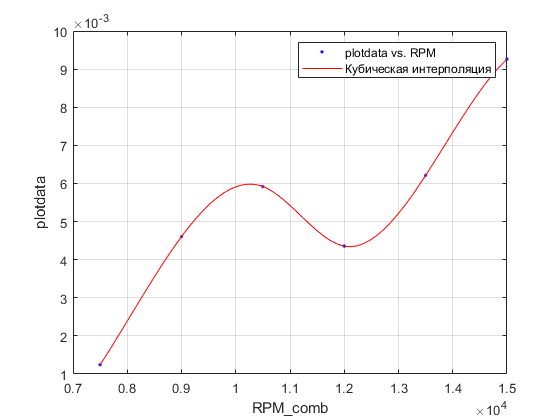

k = 34

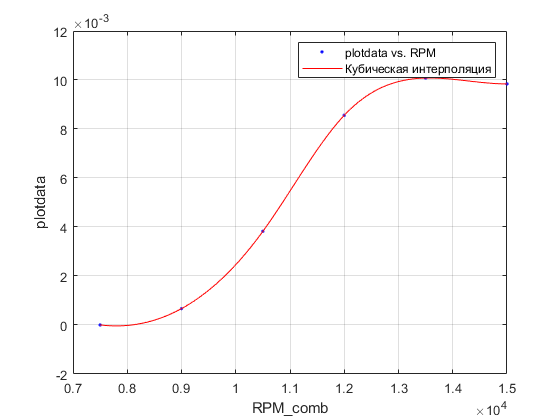

k = 35

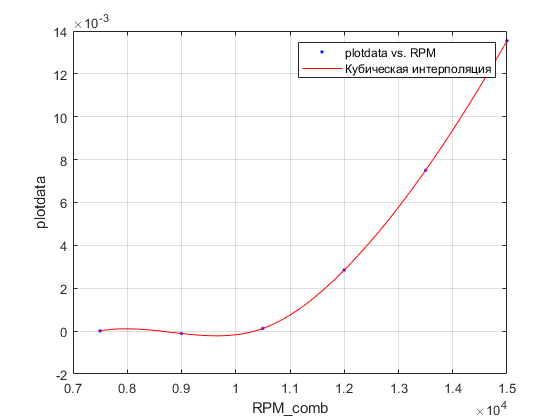

k = 36

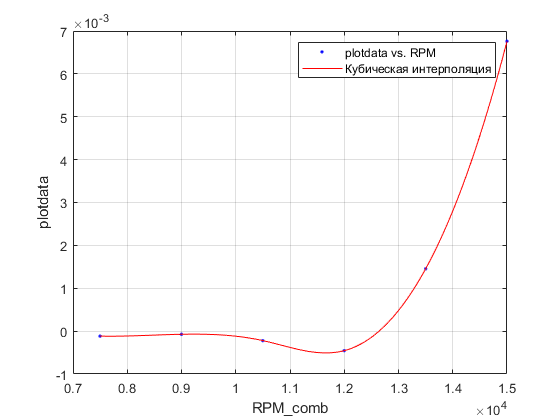

k = 37

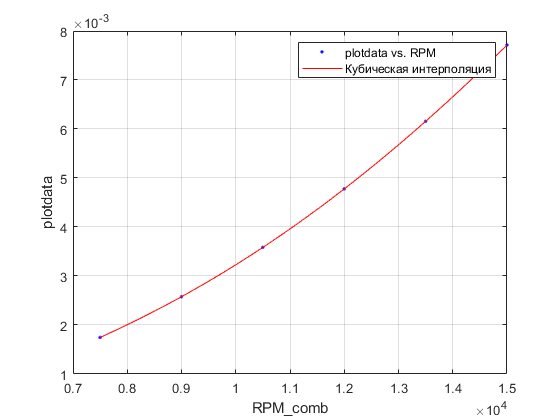

k = 38

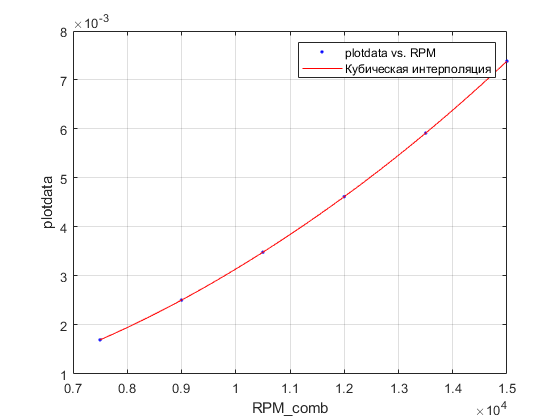

k = 39

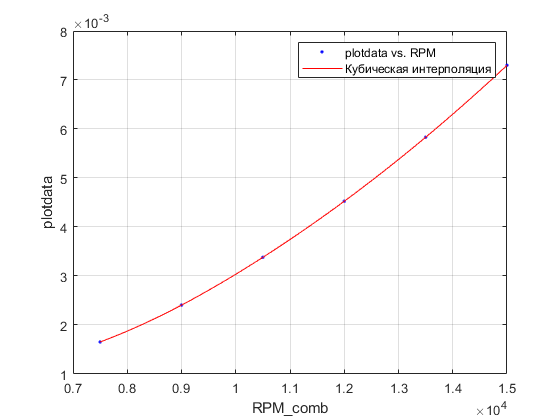

k = 40

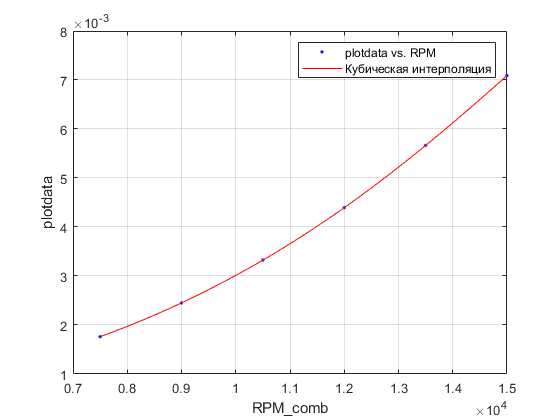

k = 41

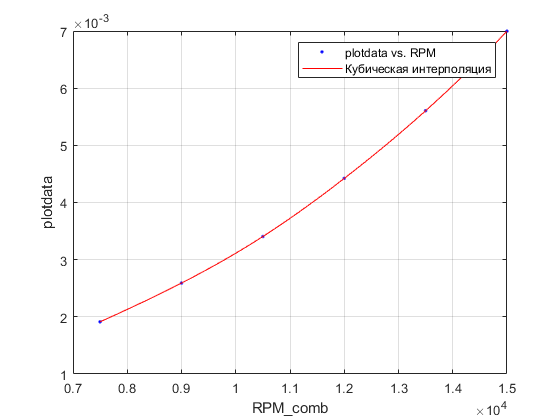

k = 42

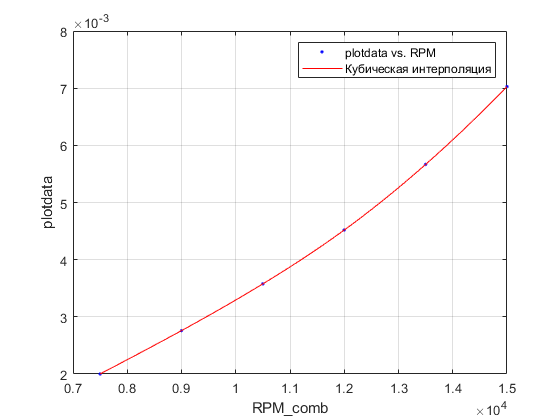

k = 43

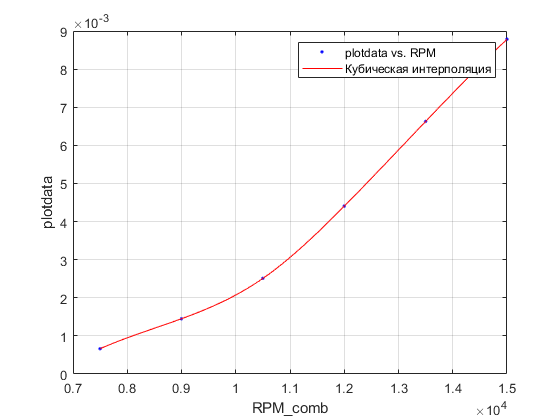

k = 44

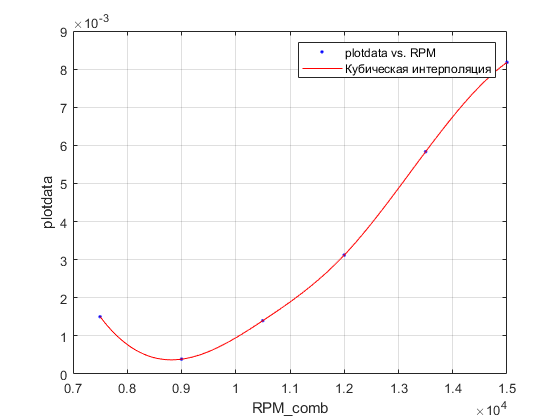

k = 45

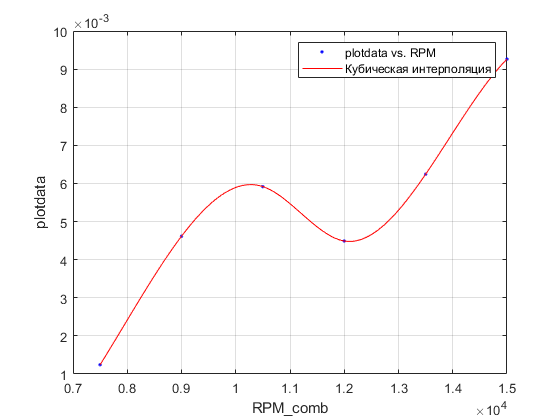

k = 46

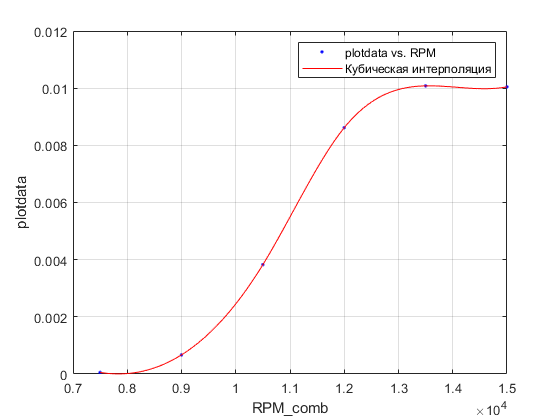

k = 47

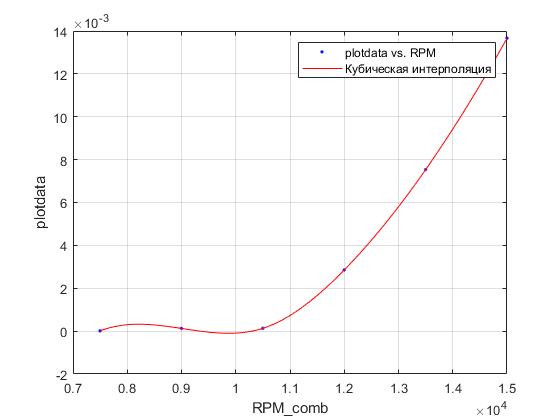

k = 48

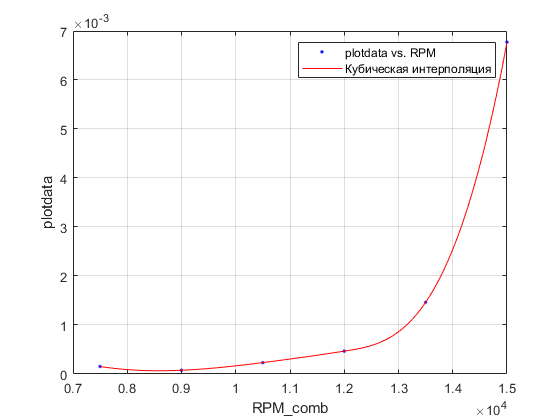


k=1;             %номер графика, их счётчик количества
for i = 1:8      %по всем силам и моментам
    for j = 1:6 %по расходам (по столбцам)
 %для всех строк (8)
    plotdata = FplusM{i,j};

    figure("Name","Силы/моменты от расхода")
%         subplot(2,3,j)
%     legstr=sprintf('Расход %.1f л/мин',k);
%     title('F'+legstr)
%         xlabel('Угл. скорость, об/мин')
%         ylabel('F [M], Н [Нм]')
%     legend(legstr,"Location","best")
%     plot(RPM_comb,cell2mat(Fr_cell(1,k)))
%     plots{k}=plot(RPM_comb,plotdata{k},'b--o')

% % Сравнение полинома и интерполяции, кубическая работает лучше!
%createFit_poly_vs_cubic(RPM_comb,plotdata);
    k
    % Сохранить каждый результат в переменную с соответствующим именем
    % (расход и частота)
     [fitresult{i,j}, gof{i,j}] = createFit_cubic_interp(RPM_comb,plotdata);  
     
%   Сохранение графиков в переменную
% plots{k}=plot(RPM_comb,plotdata,'b--o');
    k=k+1;
    end
end

Получение силы, на основании заданного расхода

clf % очистка графиков в выводе

% Ввод частоты, расхода - получение значения силы
% задаем расход (ячека определяет проекцию вектора и расход,
% первый индекс m = 1 - Fx, m=2 - Fy, m=3 - Fz, m=4 - Fr, m=5 - Mx и т.д. m=8 - Mr аналогично,
% второй индекс n = 1 - расход 1 л/мин, n=6 - расход 6 л/мин

prompt = 'Выберите величину для поиска Fx, Fy, Fz, Fr, Mx, My, Mz, Mr ?:';
str = input(prompt, 's');
if isempty(str)
    str = 'Fx';
    m=1;
    FM_flag=1; % Флаг это сила или момент? 1 - сила, 2 - момент
elseif str == "Fx"
    m=1;
    FM_flag=1;
elseif str == "Fy"
    m=2;
    FM_flag=1;
elseif str == "Fz"
    m=3;
    FM_flag=1;
elseif str == "Fr"
    m=4;
    FM_flag=1;
elseif str == "Mx"
    m=5
    FM_flag=2;
elseif str == "My"
    m=6;
    FM_flag=2;
elseif str == "Mz"
    m=7;
    FM_flag=2;
elseif str == "Mr"
    m=8;
    FM_flag=2;
end

prompt = 'Значение требуемого расхода от 1 до 6:';
n = input(prompt);
if isempty(n)
    n=1;
end

% m = 1; % выбор величины для поиска 1-4 = силы, 5-8 = моменты, см. выше
% n=1; % расход в л/мин по шкале от 1 до 6

% Простое задание частоты вращения в об/мин в пределах от 7500 до 15000
% RPMtofind = 9500;
prompt = 'Значение частоты от 7500 до 15000 об/мин:';
RPMtofind = input(prompt);
if isempty(RPMtofind)
    RPMtofind=7500;
end

plotdata = FplusM{m,n}; 

% Получаем значение силы на заданной частоте
ForceOrMoment = getForceOnRPMandFlow(RPM_comb,plotdata,RPMtofind,FM_flag)


Построение поверхности (пространства всех значений)

Расход:    1 л/мин, частота: 7500 об/мин, сила: 0.0018 Н
Расход:    1 л/мин, частота: 7600 об/мин, сила: 0.0012 Н
Расход:    1 л/мин, частота: 7700 об/мин, сила: 0.0008 Н
Расход:    1 л/мин, частота: 7800 об/мин, сила: 0.0005 Н
Расход:    1 л/мин, частота: 7900 об/мин, сила: 0.0004 Н
Расход:    1 л/мин, частота: 8000 об/мин, сила: 0.0003 Н
Расход:    1 л/мин, частота: 8100 об/мин, сила: 0.0004 Н
Расход:    1 л/мин, частота: 8200 об/мин, сила: 0.0006 Н
Расход:    1 л/мин, частота: 8300 об/мин, сила: 0.0009 Н
Расход:    1 л/мин, частота: 8400 об/мин, сила: 0.0013 Н
Расход:    1 л/мин, частота: 8500 об/мин, сила: 0.0018 Н
Расход:    1 л/мин, частота: 8600 об/мин, сила: 0.0024 Н
Расход:    1 л/мин, частота: 8700 об/мин, сила: 0.0031 Н
Расход:    1 л/мин, частота: 8800 об/мин, сила: 0.0038 Н
Расход:    1 л/мин, частота: 8900 об/мин, сила: 0.0047 Н
Расход:    1 л/мин, частота: 9000 об/мин, сила: 0.0057 Н
Расход:    1 л/мин, частота: 9100 об/мин, сила: 0.0067 Н
Расход:    1 л/мин, частота: 92

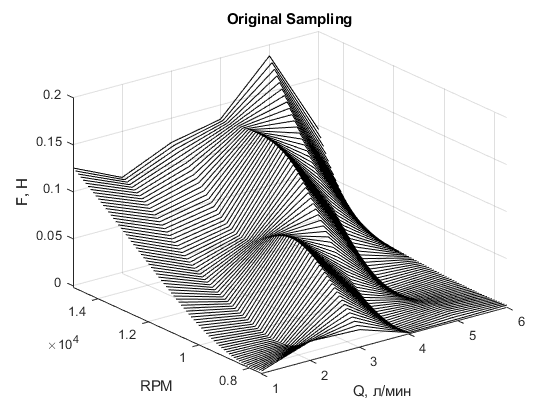

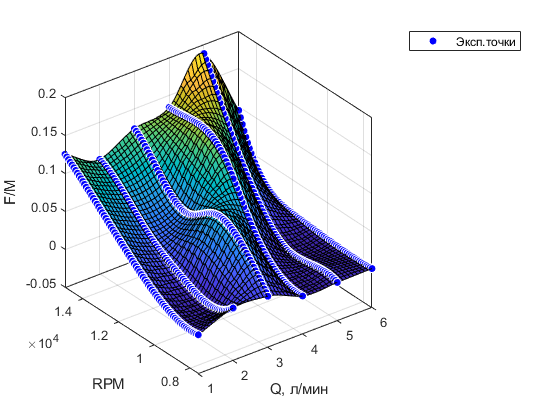

Расход:    1 л/мин, частота: 7500 об/мин, сила: 0.0050 Н
Расход:    1 л/мин, частота: 7600 об/мин, сила: 0.0059 Н
Расход:    1 л/мин, частота: 7700 об/мин, сила: 0.0067 Н
Расход:    1 л/мин, частота: 7800 об/мин, сила: 0.0076 Н
Расход:    1 л/мин, частота: 7900 об/мин, сила: 0.0083 Н
Расход:    1 л/мин, частота: 8000 об/мин, сила: 0.0091 Н
Расход:    1 л/мин, частота: 8100 об/мин, сила: 0.0098 Н
Расход:    1 л/мин, частота: 8200 об/мин, сила: 0.0104 Н
Расход:    1 л/мин, частота: 8300 об/мин, сила: 0.0111 Н
Расход:    1 л/мин, частота: 8400 об/мин, сила: 0.0117 Н
Расход:    1 л/мин, частота: 8500 об/мин, сила: 0.0122 Н
Расход:    1 л/мин, частота: 8600 об/мин, сила: 0.0127 Н
Расход:    1 л/мин, частота: 8700 об/мин, сила: 0.0132 Н
Расход:    1 л/мин, частота: 8800 об/мин, сила: 0.0137 Н
Расход:    1 л/мин, частота: 8900 об/мин, сила: 0.0141 Н
Расход:    1 л/мин, частота: 9000 об/мин, сила: 0.0145 Н
Расход:    1 л/мин, частота: 9100 об/мин, сила: 0.0149 Н
Расход:    1 л/мин, частота: 92

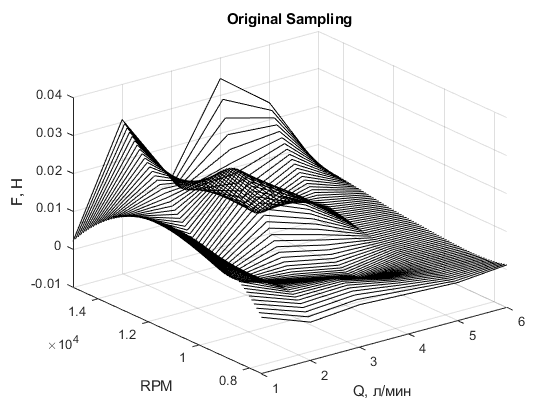

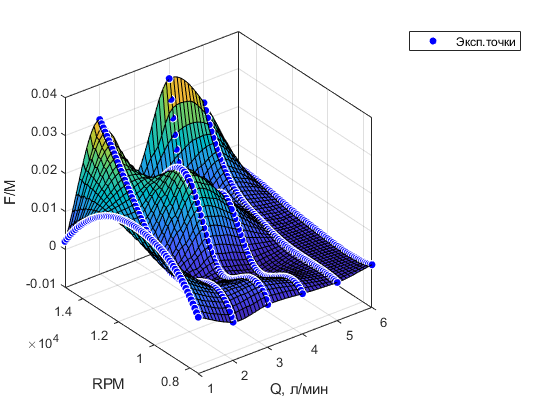

Расход:    1 л/мин, частота: 7500 об/мин, сила: -1.3121 Н
Расход:    1 л/мин, частота: 7600 об/мин, сила: -1.3499 Н
Расход:    1 л/мин, частота: 7700 об/мин, сила: -1.3883 Н
Расход:    1 л/мин, частота: 7800 об/мин, сила: -1.4273 Н
Расход:    1 л/мин, частота: 7900 об/мин, сила: -1.4668 Н
Расход:    1 л/мин, частота: 8000 об/мин, сила: -1.5069 Н
Расход:    1 л/мин, частота: 8100 об/мин, сила: -1.5476 Н
Расход:    1 л/мин, частота: 8200 об/мин, сила: -1.5888 Н
Расход:    1 л/мин, частота: 8300 об/мин, сила: -1.6306 Н
Расход:    1 л/мин, частота: 8400 об/мин, сила: -1.6730 Н
Расход:    1 л/мин, частота: 8500 об/мин, сила: -1.7160 Н
Расход:    1 л/мин, частота: 8600 об/мин, сила: -1.7595 Н
Расход:    1 л/мин, частота: 8700 об/мин, сила: -1.8037 Н
Расход:    1 л/мин, частота: 8800 об/мин, сила: -1.8484 Н
Расход:    1 л/мин, частота: 8900 об/мин, сила: -1.8937 Н
Расход:    1 л/мин, частота: 9000 об/мин, сила: -1.9397 Н
Расход:    1 л/мин, частота: 9100 об/мин, сила: -1.9862 Н
Расход:    1 л

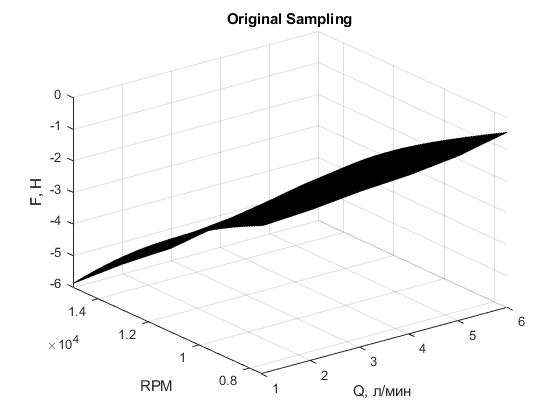

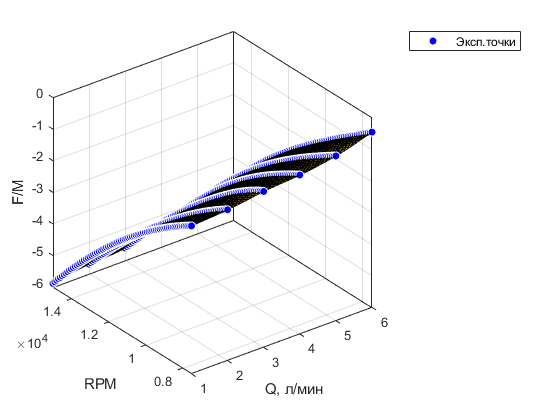

Расход:    1 л/мин, частота: 7500 об/мин, сила: 0.0053 Н
Расход:    1 л/мин, частота: 7600 об/мин, сила: 0.0059 Н
Расход:    1 л/мин, частота: 7700 об/мин, сила: 0.0065 Н
Расход:    1 л/мин, частота: 7800 об/мин, сила: 0.0071 Н
Расход:    1 л/мин, частота: 7900 об/мин, сила: 0.0077 Н
Расход:    1 л/мин, частота: 8000 об/мин, сила: 0.0083 Н
Расход:    1 л/мин, частота: 8100 об/мин, сила: 0.0089 Н
Расход:    1 л/мин, частота: 8200 об/мин, сила: 0.0096 Н
Расход:    1 л/мин, частота: 8300 об/мин, сила: 0.0102 Н
Расход:    1 л/мин, частота: 8400 об/мин, сила: 0.0109 Н
Расход:    1 л/мин, частота: 8500 об/мин, сила: 0.0116 Н
Расход:    1 л/мин, частота: 8600 об/мин, сила: 0.0124 Н
Расход:    1 л/мин, частота: 8700 об/мин, сила: 0.0131 Н
Расход:    1 л/мин, частота: 8800 об/мин, сила: 0.0139 Н
Расход:    1 л/мин, частота: 8900 об/мин, сила: 0.0148 Н
Расход:    1 л/мин, частота: 9000 об/мин, сила: 0.0156 Н
Расход:    1 л/мин, частота: 9100 об/мин, сила: 0.0165 Н
Расход:    1 л/мин, частота: 92

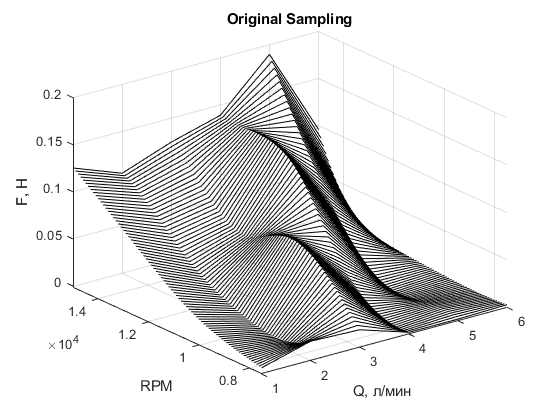

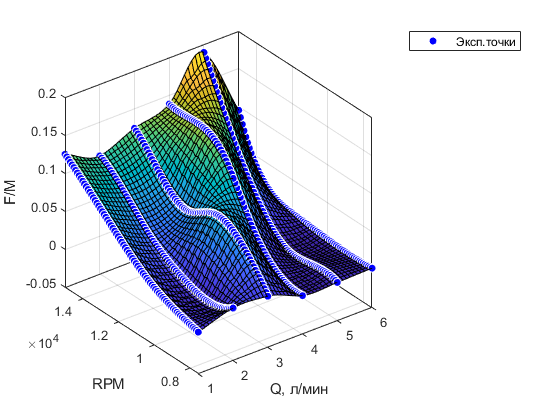

Расход:    1 л/мин, частота: 7500 об/мин, сила: 0.0006 Н
Расход:    1 л/мин, частота: 7600 об/мин, сила: 0.0007 Н
Расход:    1 л/мин, частота: 7700 об/мин, сила: 0.0008 Н
Расход:    1 л/мин, частота: 7800 об/мин, сила: 0.0008 Н
Расход:    1 л/мин, частота: 7900 об/мин, сила: 0.0009 Н
Расход:    1 л/мин, частота: 8000 об/мин, сила: 0.0010 Н
Расход:    1 л/мин, частота: 8100 об/мин, сила: 0.0010 Н
Расход:    1 л/мин, частота: 8200 об/мин, сила: 0.0011 Н
Расход:    1 л/мин, частота: 8300 об/мин, сила: 0.0011 Н
Расход:    1 л/мин, частота: 8400 об/мин, сила: 0.0012 Н
Расход:    1 л/мин, частота: 8500 об/мин, сила: 0.0012 Н
Расход:    1 л/мин, частота: 8600 об/мин, сила: 0.0013 Н
Расход:    1 л/мин, частота: 8700 об/мин, сила: 0.0013 Н
Расход:    1 л/мин, частота: 8800 об/мин, сила: 0.0014 Н
Расход:    1 л/мин, частота: 8900 об/мин, сила: 0.0014 Н
Расход:    1 л/мин, частота: 9000 об/мин, сила: 0.0014 Н
Расход:    1 л/мин, частота: 9100 об/мин, сила: 0.0015 Н
Расход:    1 л/мин, частота: 92

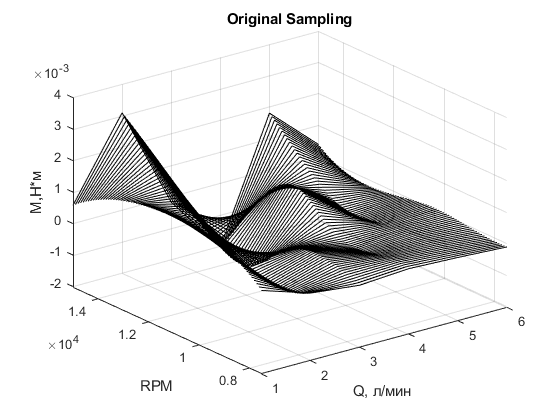

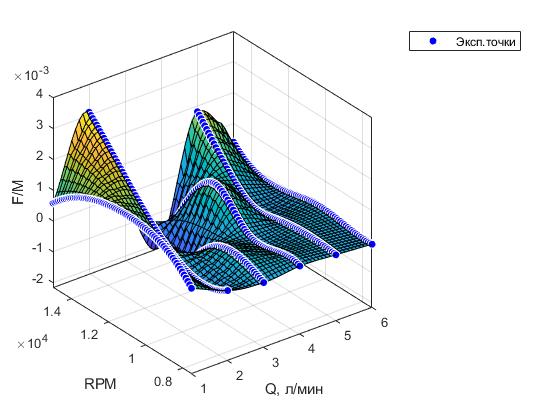

Расход:    1 л/мин, частота: 7500 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 7600 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 7700 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 7800 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 7900 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 8000 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 8100 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 8200 об/мин, сила: 0.0001 Н
Расход:    1 л/мин, частота: 8300 об/мин, сила: 0.0001 Н
Расход:    1 л/мин, частота: 8400 об/мин, сила: 0.0001 Н
Расход:    1 л/мин, частота: 8500 об/мин, сила: 0.0000 Н
Расход:    1 л/мин, частота: 8600 об/мин, сила: -0.0000 Н
Расход:    1 л/мин, частота: 8700 об/мин, сила: -0.0001 Н
Расход:    1 л/мин, частота: 8800 об/мин, сила: -0.0001 Н
Расход:    1 л/мин, частота: 8900 об/мин, сила: -0.0002 Н
Расход:    1 л/мин, частота: 9000 об/мин, сила: -0.0003 Н
Расход:    1 л/мин, частота: 9100 об/мин, сила: -0.0004 Н
Расход:    1 л/мин, часто

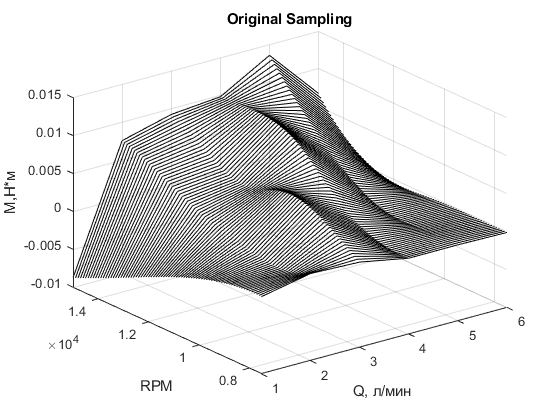

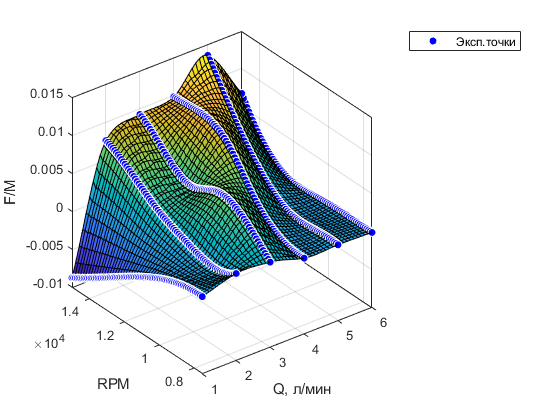

Расход:    1 л/мин, частота: 7500 об/мин, сила: 0.0017 Н
Расход:    1 л/мин, частота: 7600 об/мин, сила: 0.0018 Н
Расход:    1 л/мин, частота: 7700 об/мин, сила: 0.0018 Н
Расход:    1 л/мин, частота: 7800 об/мин, сила: 0.0019 Н
Расход:    1 л/мин, частота: 7900 об/мин, сила: 0.0020 Н
Расход:    1 л/мин, частота: 8000 об/мин, сила: 0.0020 Н
Расход:    1 л/мин, частота: 8100 об/мин, сила: 0.0021 Н
Расход:    1 л/мин, частота: 8200 об/мин, сила: 0.0021 Н
Расход:    1 л/мин, частота: 8300 об/мин, сила: 0.0022 Н
Расход:    1 л/мин, частота: 8400 об/мин, сила: 0.0022 Н
Расход:    1 л/мин, частота: 8500 об/мин, сила: 0.0023 Н
Расход:    1 л/мин, частота: 8600 об/мин, сила: 0.0023 Н
Расход:    1 л/мин, частота: 8700 об/мин, сила: 0.0024 Н
Расход:    1 л/мин, частота: 8800 об/мин, сила: 0.0025 Н
Расход:    1 л/мин, частота: 8900 об/мин, сила: 0.0025 Н
Расход:    1 л/мин, частота: 9000 об/мин, сила: 0.0026 Н
Расход:    1 л/мин, частота: 9100 об/мин, сила: 0.0026 Н
Расход:    1 л/мин, частота: 92

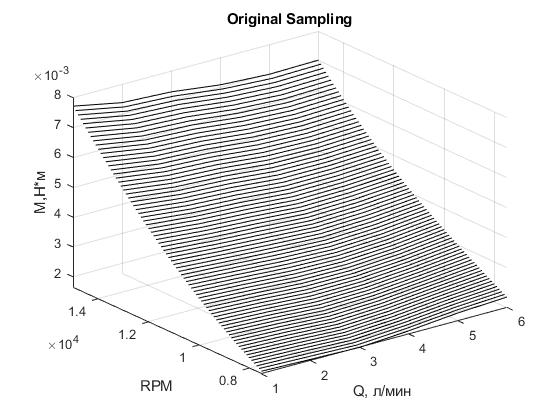

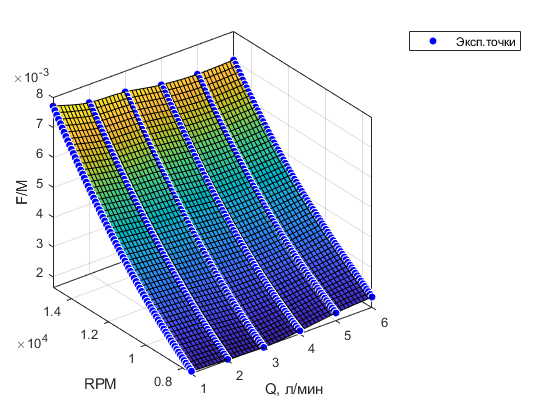

Расход:    1 л/мин, частота: 7500 об/мин, сила: 0.0007 Н
Расход:    1 л/мин, частота: 7600 об/мин, сила: 0.0007 Н
Расход:    1 л/мин, частота: 7700 об/мин, сила: 0.0008 Н
Расход:    1 л/мин, частота: 7800 об/мин, сила: 0.0008 Н
Расход:    1 л/мин, частота: 7900 об/мин, сила: 0.0009 Н
Расход:    1 л/мин, частота: 8000 об/мин, сила: 0.0009 Н
Расход:    1 л/мин, частота: 8100 об/мин, сила: 0.0010 Н
Расход:    1 л/мин, частота: 8200 об/мин, сила: 0.0011 Н
Расход:    1 л/мин, частота: 8300 об/мин, сила: 0.0011 Н
Расход:    1 л/мин, частота: 8400 об/мин, сила: 0.0012 Н
Расход:    1 л/мин, частота: 8500 об/мин, сила: 0.0012 Н
Расход:    1 л/мин, частота: 8600 об/мин, сила: 0.0012 Н
Расход:    1 л/мин, частота: 8700 об/мин, сила: 0.0013 Н
Расход:    1 л/мин, частота: 8800 об/мин, сила: 0.0013 Н
Расход:    1 л/мин, частота: 8900 об/мин, сила: 0.0014 Н
Расход:    1 л/мин, частота: 9000 об/мин, сила: 0.0015 Н
Расход:    1 л/мин, частота: 9100 об/мин, сила: 0.0015 Н
Расход:    1 л/мин, частота: 92

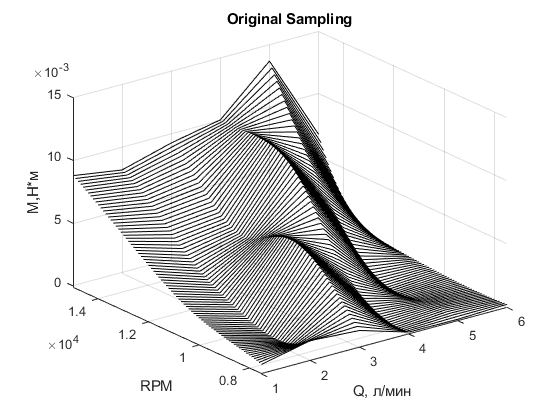

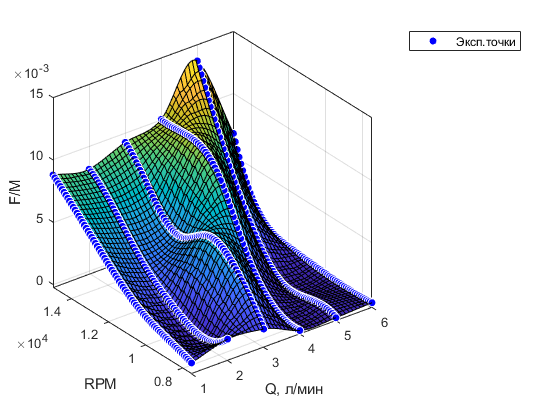

clf % очистка графиков в выводе
clear all
load('FplusM.mat',"FplusM","RPM_comb");
FM_flag=0;           % Если не 1 или не 2, то не строим графики, получаем только силу
% Q=[1 2 3 4 5 6];
Q = linspace(1,6,6);
RPM_all = 1:15000;

% myVector = zeros(4)
% nxm = 24
F_points_all = zeros(6,15000);

F_points_all(F_points_all==0) = NaN;

for m=1:8 % m = 1 - Fx, m=2 - Fy, m=3 - Fz, m=4 - Fr, m=5 - Mx и т.д. m=8 - Mr
% for m = 1:8         %по всем силам  %моментам 5-8 (построчно)
    for n = 1:6     %по расходам (по столбцам)
        plotdata = FplusM{m,n}; % получаем значение вектора силы или момента на частотах
        for RPMtofind = 7500:100:15000
%             m
%             n
%             RPMtofind

%             RPM = RPMtofind
            % Получаем значение силы на заданной частоте и расходе
            Force_point = getForceOnRPMandFlow(RPM_comb,plotdata,RPMtofind,FM_flag);
            formatSpec = 'Расход: %4.0f л/мин, частота: %4.0f об/мин, сила: %4.4f Н\n';
            fprintf(formatSpec,n,RPMtofind,Force_point)
            % Нужно записать в ячейку матрицы значение силы
            F_points_all(n,RPMtofind) = Force_point;
%             F_vect(RPMtofind) = Force_point;
%             Table_F_points.n(RPMtofind) = Force_point;
            
        end
    end

%Построение поверхностей
% F_points_all=F_points_all(F_points_all~=0)

F_tr=F_points_all.';
[X,Y]=meshgrid(Q,RPM_all);
figure
plot3(X,Y,F_tr,'marker',"o")


surf(X,Y,F_tr)
title('Original Sampling');


xlabel('Q, л/мин')
ylabel('RPM')
if m<=4
    zlabel('F, Н')
else
   zlabel('М,Н*м') 
end
grid on

[xData, yData, zData] = prepareSurfaceData( X, Y, F_tr );

f = fit([xData, yData],zData,'cubicinterp'); % 'linearinterp' poly11 'lowess' biharmonicinterp thinplateinterp
% Library Model Name
% Description
% 'poly1'
% Linear polynomial curve
% 'poly11'
% Linear polynomial surface
% 'poly2'
% Quadratic polynomial curve
% 'linearinterp'
% Piecewise linear interpolation
% 'cubicinterp'
% Piecewise cubic interpolation
% 'smoothingspline'
% Smoothing spline (curve)
% 'lowess'
% Local linear regression (surface)

figure('Name',"Интерполяция");
title('Интерполяция ');
plot( f, [xData, yData],zData)
xlabel('Q, л/мин')
ylabel('RPM')
zlabel('F/М') 
legend('Эксп.точки')

% filename = ""
save(['interpdata/Q_' num2str(m) '.mat'],'xData')
save(['interpdata/RPM_' num2str(m) '.mat'],"yData")
save(['interpdata/FM_' num2str(m) '.mat'],"zData")
% save(['interpdata/FM_' num2str(j) '.mat'],'X')

Srfc(m).x = xData;
Srfc(m).y = yData;
Srfc(m).z = zData;
Srfc(m).f = f;
save("Srfc.mat","Srfc");
% T(m). = table(xData,yData,zData)

end


% должны пробежаться по ключевым значениям и построить по ним модель
% (извлечь коэффициенты) ?!?
% затем эти кривые сохранить и подгрузить в систему
% управления, чтобы можно было доставать значения с кривых

Интерполирванные результаты

load("Srfc.mat","Srfc");
Fit = findPoint(Srfc,3.5,11200);

function [Fit] = findPoint(Srfc,Q_to_find,RPM_to_find)
for m = 1:8
    
    xData = Srfc(m).x;
    yData = Srfc(m).y;
    zData = Srfc(m).z;
    f = Srfc(m).f;
    %     f = fit([xData, yData],zData,'cubicinterp'); % 'linearinterp'
    % find point
    
        figure('Name',"Интерполяция");
    point_Z = feval(f,Q_to_find,RPM_to_find)
  
%     point_Y = feval(f,RPM_to_find);
%     point_Z = f(point_X,point_Y);
%     h1 = plot(Q_to_find,RPM_to_find,point_Z, 'o');

    title('Интерполяция');
%     hold on
    plot( f, [xData, yData],zData)
    hold on
%     h= scatter3(Q_to_find,RPM_to_find,point_Z,'filled',"r*");
%     plot3(Q_to_find,RPM_to_find,point_Z,"rx",'MarkerSize',10)
%      h.SizeData=250;
    plot3(Q_to_find,RPM_to_find,point_Z,"r*",'MarkerSize',10)
   
    xlabel('Q, л/мин')
    ylabel('RPM')
        if m<=4
            zlabel('F, Н')
        else
            zlabel('М,Н*м') 
        end
    legend('Эксп.точки','Найденное значение', 'Location', 'best', 'Interpreter', 'none' )
    hold off
    % Get Moment or Force values from model
    %     z2=f(xData,yData)
    if m<5
        Fit(m).F=f(Q_to_find,RPM_to_find)
    else
        Fit(m).M=f(Q_to_find,RPM_to_find)
    end

end
end
